# Exploring grouped data with gramm

In this example file, we will go further in exploring gramm's capabilities for data where the independent variables are categorical / group data.

To benefit from interactive elements, you should open it in MATLAB's editor with

We will load a partial dataset from a human movement science experiment

load example_movement.mat
T

T = 3170×15 table
    subject    session    trial_index    reference_direction    hit    m_movement_duration    m_dist    m_reaction_time                 target_pos                  valid_perc    valid_perc_session                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

In this dataset, we have four different subjects (`subject`), each coming for two sessions (`session`) on consecutive days at the lab. During each of these sessions they learn to control the displacement of a cursor on a screen, and their task is to reach targets with the cursor. The targets are arranged at discrete angles (`reference direction`) in a circle around a starting point. The cursor is difficult to control, and as a marker for progress, we record whether they reach the target in time (`hit`), how long was their reaction time (`m_reaction_time`), their movement (`m_movement duration`), and what was the distance covered by the cursor (`m_dist`). Each line corresponds to a trial (`trial_index`), and we transformed the index in percentage of time elapsed within session (`valid_perc`) or across sessions (`valid_perc_session`)

## Using categorical data on the x axis

First let's examine the progress (using the reaction time `m_reaction_time`) between session for each subject. With gramm it's possible to use categorical data on the x axis and thus reproduce typical raw data plots or statistical data plots that would accompany analyses such as ANOVAs.

**Interactive parameter:** To avoid points from both sessions to overlap, we use the `'dodge'` parameter in `geom_point()`. The numerical value indicates the spacing along the x axis used to avoid the overlap.

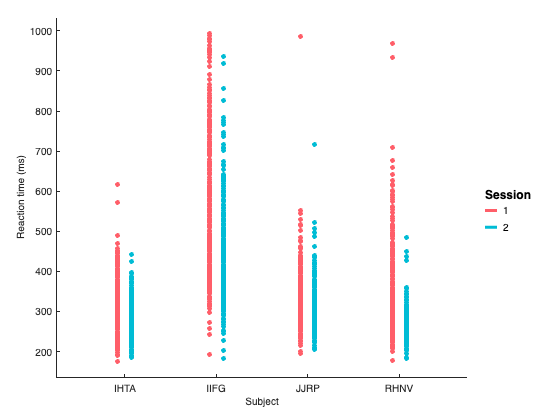

figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_point('dodge',0.3);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

Here we see that even with using the 'dodge' argument, the basic `geom_point()` is limited becaus of the overlap between points. We have two other `geom_` methods that can make this better. 

## Improving the visualization of raw datapoints

### Randomly jitter points with geom_jitter() and dodge graphical elements

A first option is to use geom_jitter() instead of geom_point() so that the datapoins are jittered along the x-axis. 

**Interactive parameters:**

- The `'width' `parameter sets the width along the x axis used for the visualization (here the width of jittering). Setting it below  the value used for `'dodge'` allows for a small spacing between points for session 1 and 2. Setting a larger value could make the points overlap. Most `geom_ `and `stat_` methods have these parameters set with usable default values as used later, but they often require tweaking depending on the complexity of your data and figure size.

- We can also make the individual points transparent with the `'alpha' `parameter

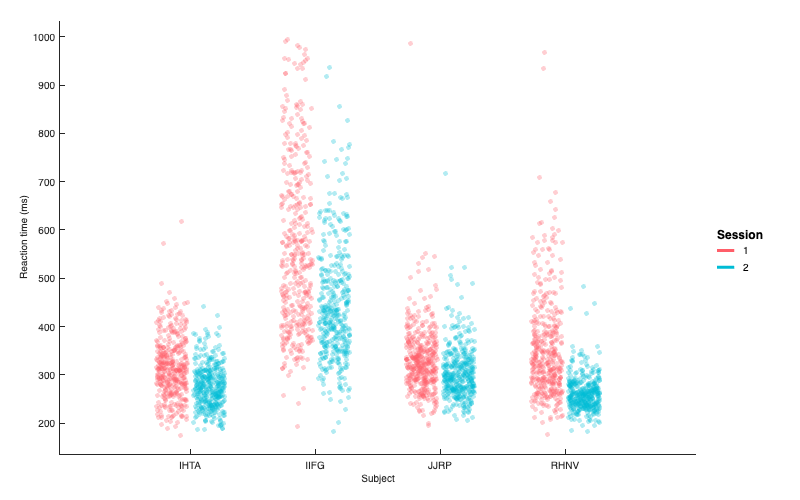

figure('Position',[100 100 800 500])
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_jitter('dodge',0.6,'width',0.5,'alpha',0.3);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

Here we better visualize the underlying distribution, however it's still difficult to get an idea with the mass of points in the middle of the distribution.

### Create a beeswarm plot with geom_swarm()

Another option to display raw datapoints is to to use a swarm plot, which stacks datapoints horizontally

**Interactive parameters:**

-  Here we set the `'point_size' `parameter for `geom_swarm()` given the large amount of points in our dataset. geom_swarm is designed so that points within a group never overlap, so big points would make each swarm large.

- The '`type'` parameter configures the way the swarm is constructed

- The `'corral'` parameter configures what happens to points that are placed further to the left and right than the width.

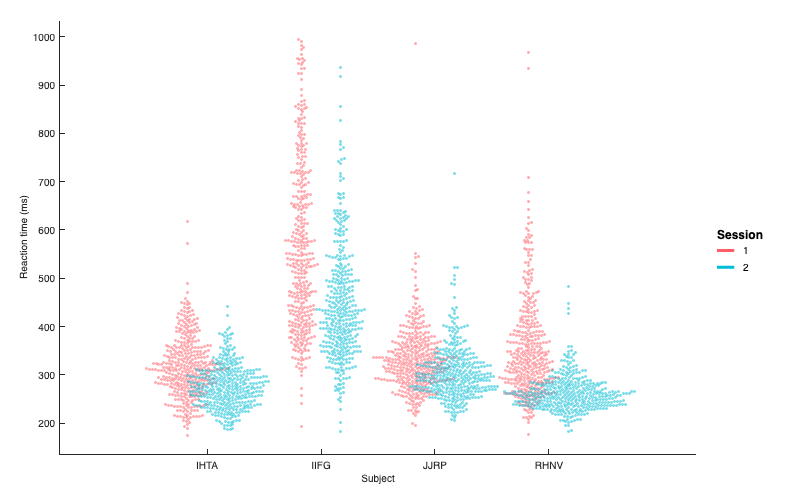

figure('Position',[100 100 800 500])
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_swarm('alpha',0.5,'point_size',1.5,'type','up','corral','none');
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

## Adding statistics layers

Now that our we displayed our raw dataset, we can add more statistics oriented visualizations to our graphs. Note that all stat_ layers could be combined with geom_ layers or together.

### Compare distributions vertically or horizontally

gramm provides two common statistical visualizations for comparing the distributions of grouped data:** box and whisker plots** or **violin plots**. You can pick one below with the first dropdown menu.

**Interactive parameters:**

- The `coord_flip()` button runs the corresponding method, which allows to flip x an y axes and thus to represent have horizontal visualizations.

- Box and whisker plots can have a `'notch' `or not

-  When comparing only two groups, violin plots can be set to show only half violins with 'half'

- The `'fill' `option allows to pick between different styles

- The `'normalization' `option is used to set up how each violin width is normalized in order to be able to compare groups with different sizes

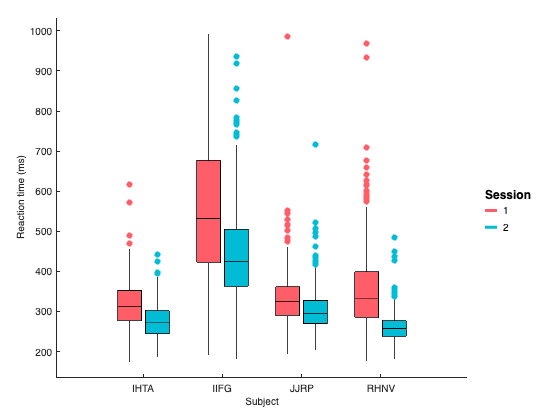

vis = "stat_boxplot";
flip = false;


figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
switch vis
    case "stat_boxplot"
        g.stat_boxplot('notch',false);
    case "stat_violin"
        g.stat_violin('width',0.5,'half',false,'fill',"transparent",'normalization','area');
end
if flip
    g.coord_flip();
end
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

### Summarize data

The `stat_summary()` layer can represent different descriptive statistics with various types of graphical elements : bars, points, errorbars, lines, shaded areas, etc. This layer is closest to the output of a statistical test such as an ANOVA or t-test. By default it represents the mean and 95% confidence interval of the mean for the group. Note that the 95% confidence interval is computed independently for each group as gramm can't know your experimental design (no multiple comparison correction).

**Interactive parameters:**

- The `'geom'` parameter specifies how the descriptive statistics are represented. The parameter can be given as a single string or as a cell of strings to combine them together. Here you can try a combination of two

- The `'setylim'` parameter determines whether the Y scale depends on the summay only or encompasses the whole dataset

- The `'type'` parameter specifies which descriptive statistics are used and how they are computed. The defaults 95% confidence interval assumes a normal distribution, but other disributions can be picked or a bootsrapped confidence interval.

- stat_summary() can be used for continuous or time series data. These uses are detailed in the corresponding live scripts.

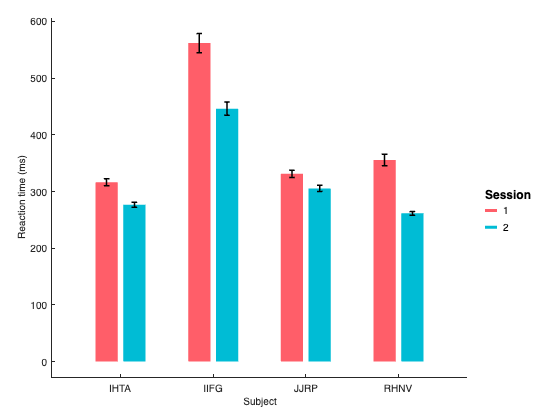


figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.stat_summary('geom',{'bar','black_errorbar'},'setylim',true,'type','ci');
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

Overall this figure confirms the large between-subject variability in the reaction time and shows that all subjects have a lower reaction time on the second day.

## Advanced example

In this last figure, we will overlay on top of the swarm plot the group median using `stat_summary()`. After the drawing is done, we will access the handles of the graphical elements through the `results` structure within the gramm object to make the medians more visible

mods = true;

figure('Position',[100 100 800 500])
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_swarm('alpha',0.5,'point_size',1.5);
g.stat_summary('dodge',0.7,'geom','black_point','type','quartile');
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

% Most of the data and graphic handles created by layers can be accessed
% through the results structure
if mods
    set([g.results.stat_summary.point_handle],'Marker','s');
    set([g.results.stat_summary.point_handle],'MarkerSize',10);
end
%Export

ans = '/private/var/folders/7y/fc4pvx655qg6k9bmc55sd1dh0000gn/T/Editor_xmofo/LiveEditorEvaluationHelperE1779447240'

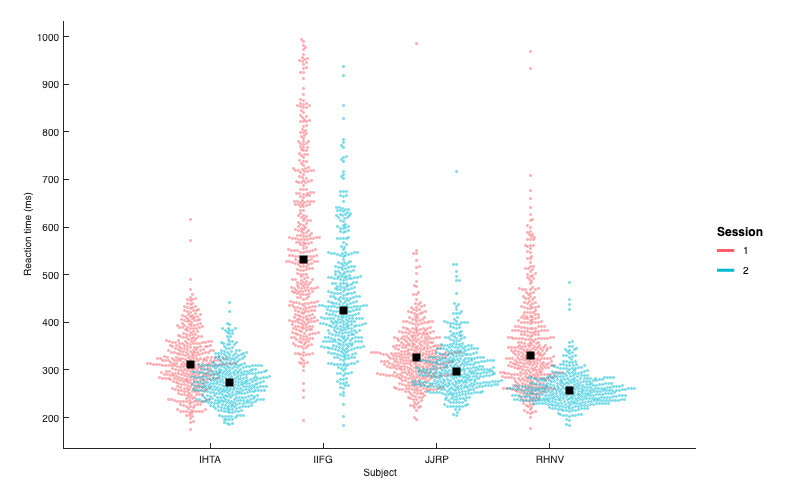

g.export('file_name','groups_export','file_type','png');